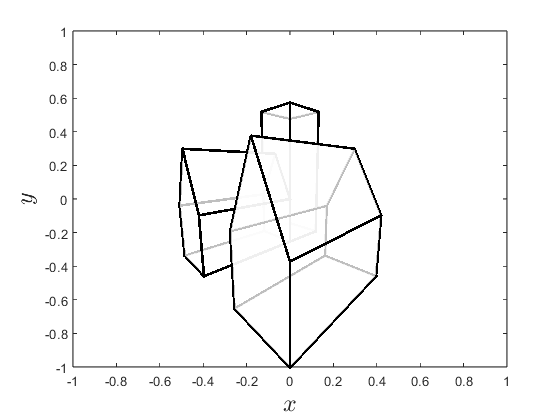

clear

% Load world space coordinates
load('camera_space_coords.mat')

% Define projection parameters
near = 1;
far = 9;
fov = pi/3;
aspect = 4/3;

% Calculate projection matrix
r = 2 * tan(fov / 2);
t = r / aspect;
P = [-near / r, 0, 0, 0 ;
     0, -near / t, 0, 0 ;
     0, 0, (near + far) / (near - far), 2 * near * far / (near - far) ;
     0, 0, 1, 0 ];

% Calculate screen space co-ordinates
Vscreen = P * Vcamera;
Vscreen = Vscreen ./ Vscreen(4,:);

% Plot camera space (from viewing position)
figure()
patch('Vertices', Vscreen(1:3,:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75, LineWidth=2)
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
view(0,90)
axis([-1, 1, -1, 1, -1, 1])
box on

exportgraphics(gcf,'../images/screen_space_example.png','Resolution',300) 